## Histogram of oriented gradients

clc;
close all;
clear variables;

### Loading files

input_file_subfolder = 'data\preprocessed\binarized\training';
intput_file_expension = 'bmp';

input_files = dir(input_file_subfolder + "/" +  "*." + intput_file_expension)

input_files = 435×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


### Example file

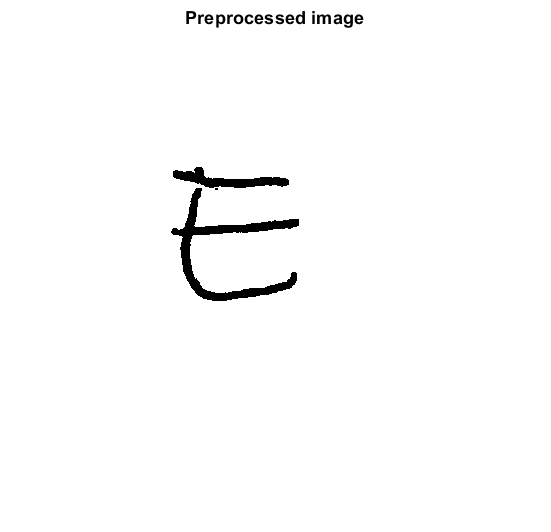

input_file = input_files(121);
file_path = input_file.folder + "\" + input_file.name;
img = imread(file_path);
figure()
imshow(img)
title('Preprocessed image')

### Feature extraction

cell_size = 16;
[featureVector, hogVisualization] = extractHOGFeatures(img, 'CellSize',[cell_size cell_size]);
size(featureVector)

ans =            1       18900


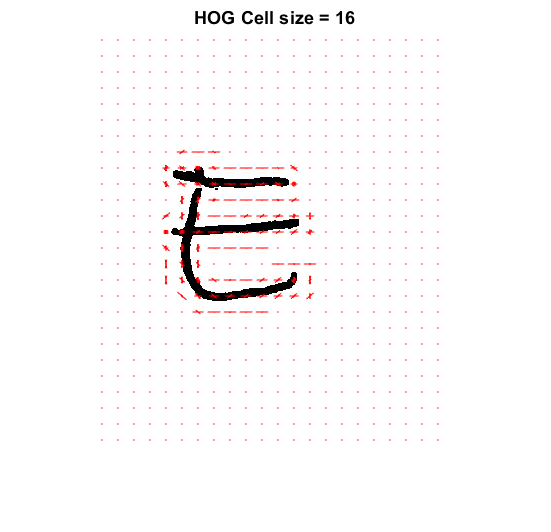

figure;
imshow(img); 
hold on;
plot(hogVisualization, 'Color', 'Red');
title("HOG Cell size = " + cell_size)

### Get training data

training_set = Dataset();